# Eigenvalues and Eigenvectors: An In-Depth Exploration

## Introduction

Eigenvalues and eigenvectors are fundamental concepts in linear algebra with extensive applications across various fields, including physics, engineering, computer science, and statistics. They play a crucial role in understanding the behavior of linear transformations and are used in numerous computational algorithms.

## Definition and Basic properties

An eigenvalue is a scalar, denoted by $\lambda$, and an eigenvector is a nonzero vector, denoted by $\textbf{v}$, that satisfy the equation:


$$A\textbf{v}=\lambda\textbf{v}$$


Here, $A$ is a square matrix. This equation implies that when the matrix $A$ acts on the eigenvalue $\textbf{v}$, it simply scales $\textbf{v}$ by the factor $\lambda$.

Mathematically the eigenvalue problem can be framed as follows: Given a square amtrix $A$, find the scalars $\lambda$ and nonzero vectors $\textbf{v}$ such that the equation above holds true. The eigenvectors corresponding to an eigenvalue $\lambda$ span an eigenspace, which is the null space of the matrix $A-\lambda I$, where $I$ is the identify matrix.

## Finding Eigenvalues

To find the eigenvalues of a matrix $A$, we need to solve the characteristic equation:


$$det(A-\lambda I)=0$$


This determinant is a polynomial in $\lambda$, known as the characterstic polynomial. The roots of this polynomial are the eigenvalues of $A$.

## Finding Eigenvectors

Once the eigenvalues are determined, the eigenvectors can be found by solving the linear system:


$$(A-\lambda I)\textbf{v}=0$$


For each eigenvalue $\lambda$, this equation is solved to find the corresponding eigenvectors.

## Eigvenvalue Decomposition

If $A$ is a square matrix, the eigenvalue decomposition (or spectral decomposition) is a factorization of $A$ into the form:


$$A = V\Lambda V^{-1}$$


Here, $V$ is a matrix whose columns are the eigenvectors of $A$, and $\Lambda$ is a diagonal matrix whose diagonal element are the eigenvalues of $A$. This decomposition is only possible if $A$ has a full set of linearly independent eigenvectors.

If $A$ is nonsingular, this decomposition can be expressed as:


$$A=V\Lambda V^{-1}$$


A common application of eigenvalue decomposition is in solving differential equations. For example, consider the differential equation $\frac{dx}{dt}=A\textbf{x}$. The solution to this equation can be expressed in terms of the matrix $\textbf{x}(t)=e^{At}\textbf{x}(0)$.

## Example

Consider the matrix:

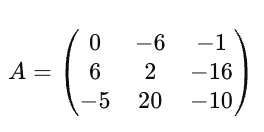

To find the eigenalues, we solve the characteristic equation:


$$det(A-\lambda I)=0$$


After finding the eigenvalues, we can find the eigenvectors by solving:


$$(A-\lambda I)\textbf{v}=0$$


In MATLAB, this can be done using **'eig'** function:

A = [0 -6 -1; 6 2 -16; -5 20 -10];
[V, D] = eig(A); % V = eigenvectors & D = Eigenvalues
disp('Eigenvectors:');

Eigenvectors:


disp(V);

  -0.8326 + 0.0000i   0.2003 - 0.1394i   0.2003 + 0.1394i
  -0.3553 + 0.0000i  -0.2110 - 0.6447i  -0.2110 + 0.6447i
  -0.4248 + 0.0000i  -0.6930 + 0.0000i  -0.6930 + 0.0000i


disp('Eigenvalues:');

Eigenvalues:


disp(D);

  -3.0710 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -2.4645 +17.6008i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -2.4645 -17.6008i


## Schur Decomposition

Many advanced matrix computations do not require eigenvalues decomposition. They are based instead on the Schur decomposition, which factors a matrix $A$ as:


$$A=USU^*$$


Here, $U$ is an orthogonal matrix, and $S$ is a block upper-triangle matrix 1-by-1 and 2-by-2 blocks on the diagonal. The eigenvalues are revealed by the diagonal elements and blocks of $S$, while the columns of $U$ provide an orthogonal basis. This method often has better numerical propeties than using a set of eigenvectors.

## Example

Consider the matrix

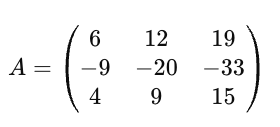

We can compare the eigenvalue and Schur decomposition of this defective matrix using MATLAB :

A = [6 12 19; -9 -20 -33; 4 9 15];
[V, D] = eig(A);
[U, S] = schur(A);

disp('Eigenvalue Decomposition:');

Eigenvalue Decomposition:


disp('Eigenvectors:')

Eigenvectors:


disp(V);

  -0.4741 + 0.0000i  -0.4082 - 0.0000i  -0.4082 + 0.0000i
   0.8127 + 0.0000i   0.8165 + 0.0000i   0.8165 + 0.0000i
  -0.3386 + 0.0000i  -0.4082 + 0.0000i  -0.4082 - 0.0000i


disp('Eigenvalues:');

Eigenvalues:


disp(D);

  -1.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 - 0.0000i


disp('Schur Decomposition');

Schur Decomposition


disp('U:');

U:


disp(U);

   -0.4741    0.6648    0.5774
    0.8127    0.0782    0.5774
   -0.3386   -0.7430    0.5774


disp('S:');

S:


disp(S);

   -1.0000   20.7846  -44.6948
         0    1.0000   -0.6096
         0    0.0000    1.0000


In this example, the Schur decomposition is particularly useful when $A$ does not have a full set of linearly independent eigenvectors, as it provides a numerically stable alterantive.

## Conclusion

Eigenvalues and eigenvectors are crucial for understanding the behavior of linear transformations and have wide-ranging applications in science and engineering. From solving differential equations to performing stability analysis and data compression, these concepts are foundational to many advanced mathematical and computational techniques. Understanding eigenvalue and Schur decompositions, as well as their properties and applications, provides a deeper insight into the structure and behavior of matrices.